# PCA

## **practice: Application of PCA in Pointcloud Orientation Estimation**

## Point Cloud Visualization

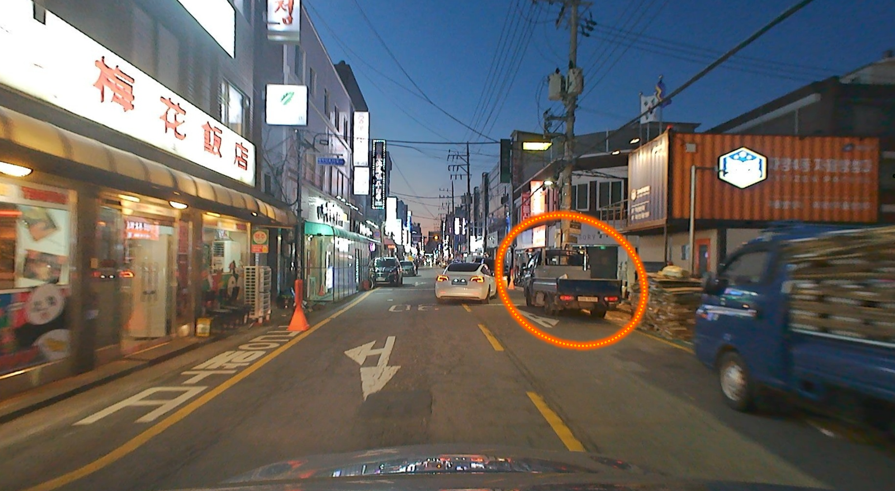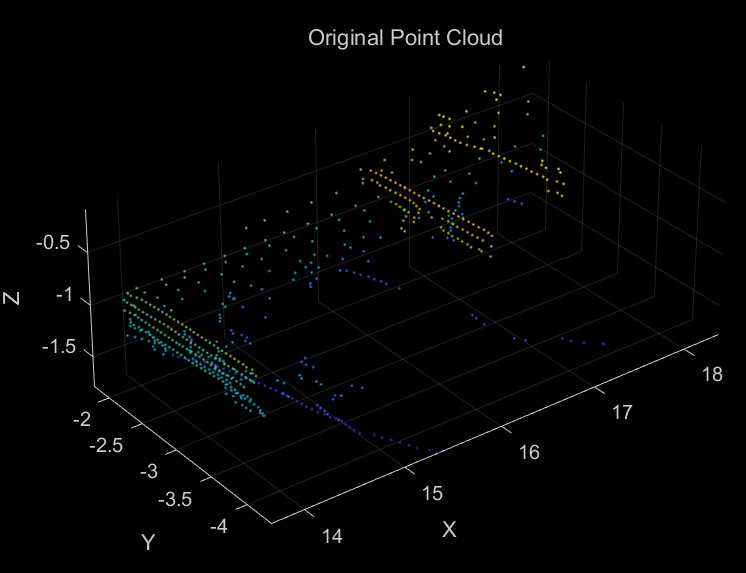

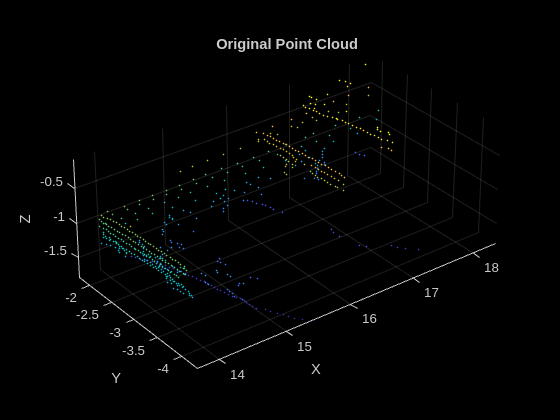

% Load pcd file
pcdFilePath = '/home/kmw/Downloads/matlabexercise/truck.pcd';

% Read pcd format file using pcread
ptCloud = pcread(pcdFilePath);

% Extract pointcloud location data
points = ptCloud.Location;

% Visualize pointcloud data
figure;
pcshow(ptCloud);
title('Original Point Cloud');
xlabel('X');
ylabel('Y');
zlabel('Z');

## Solve PCA

% Calculate midpoint of all point cloud
meanPoints = mean(points);

% Subtract the midpoint for all point cloud
%%%%%%% TODO %%%%%%%
centeredPoints = points - meanPoints;
%%%%%%%%%%%%%%%%%%%%

% Calculate Covarinace matrix
covarianceMatrix = cov(centeredPoints);

% Eigendecomposition
[eigenVectors, eigenValues] = eig(covarianceMatrix);

% Sorting Eigenvalue
[eigenValuesSorted, order] = sort(diag(eigenValues), 'descend');
eigenVectorsSorted = eigenVectors(:, order);

% Get principal component vector
%%%%%%% TODO %%%%%%%
principalDirection = eigenVectorsSorted(:, 1);
%%%%%%%%%%%%%%%%%%%%

## Visualize result of PCA

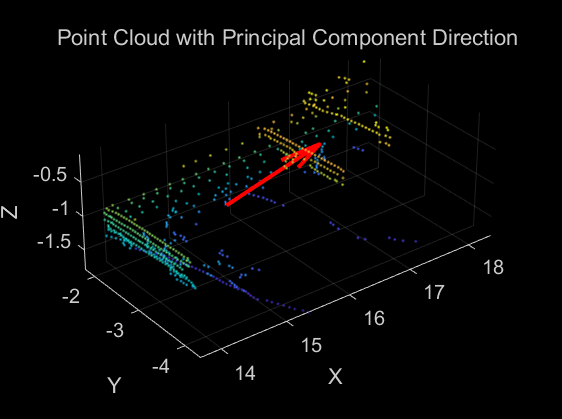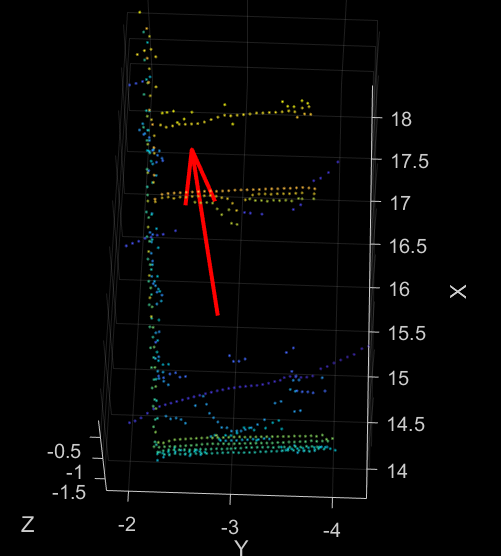

**                                                                           Viewpoint1                                                                                                               Viewpoint2**

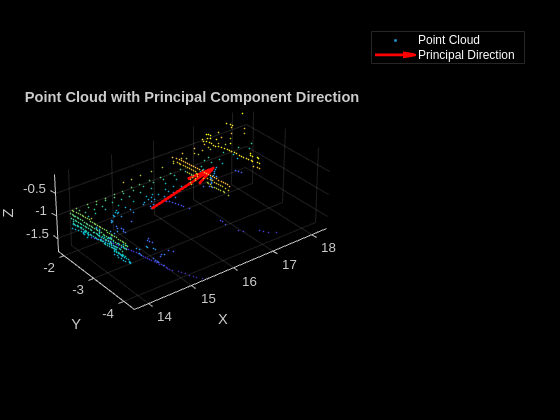

hold on;
quiver3(meanPoints(1), meanPoints(2), meanPoints(3), ...
        principalDirection(1)*2, principalDirection(2)*2, principalDirection(3)*2, ...
        'r', 'LineWidth', 2, 'MaxHeadSize', 2);
hold off;

title('Point Cloud with Principal Component Direction');
h_legend = legend('Point Cloud', 'Principal Direction'); 
set(h_legend, 'TextColor', 'w'); 
xlabel('X');
ylabel('Y');
zlabel('Z');